# Sign Perturbed sums

#### Data generator

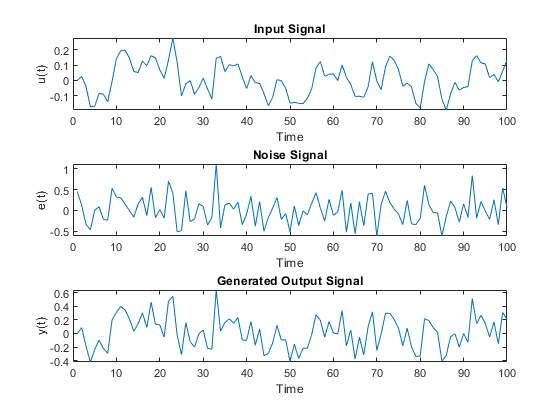

% Define ARX model parameters
% y(t) - 0.44 y(t-1) = 0.33u(t-1) + 0.7e(t) 
% u(t) = 0.31 y(t) + 0.23 y(t-1) controller
A = [1, -0.44];   % AR coefficients
B = [0.33];       % MA coefficients
C = [0.7];       % input coefficients
D = 0;           % Constant term
noiseVar = 0.1;  % Variance of the noise

% Create an instance of ARMAXGenerator
armaxGen = ARMAXGenerator(A, B, C, D, @custom_past_y);

% Generate data
n = 100; % Number of data points
e = sqrt(noiseVar) * randn(n, 1); % Noise sequence
[y, u, e] = armaxGen.generateData(n,e);
% Plot the generated data
armaxGen.plotData(y, u, e);

SPS 

% Define confidence probability and number of random signs
% Define SPS parameters
p = 0.95; % Confidence probability p = 1 − q/m
m = 10;   % Integer m
q = 1;    % Integer q 

% Create an instance of SPS
sps = SPS(p, m, q, n);
% Generate random signs and permutation
sps = sps.generateRandomSignsAndPermutation();
X = createFeatureMatrix(y,u);
%theta_hat = sps.estimateParameters(X, y);

theta_hat = [-0.5, 0.5]';
% Make predictions with new data
y_pred = sps.predictor(X, theta_hat);
% PE
y_errors = y-y_pred;
% build m-1 sequences of sign perturbed prediction errors
sp_errors = sps.alpha.*y_errors';

A_star = [1, theta_hat(1)];
B_star = [theta_hat(2)];
C_star = [1];
D_star = 0;

% Create an instance of ARMAXGenerator
armaxGen_bar = ARMAXGenerator(A_star, B_star, C_star, D_star, @custom_past_y);

y_bar = zeros(m, n);
u_bar = zeros(m, n);
x_size = size(X);
X_bar = zeros(m, x_size(1), x_size(2));

y_bar(1,:) = y;
u_bar(1,:) = u;
X_bar(1,:,:) = X;


for k = 2:m 
    [y_bar(k,:), u_bar(k,:), ~] = armaxGen.generateData(n,sp_errors(k-1,:)');
    X_bar(k,:,:) =  createFeatureMatrix(y_bar(k,:),u_bar(k,:));
    %armaxGen.plotData(y_bar(k,:), u_bar(k,:), sp_errors(k,:)');
end







Aux function

function u_out = step_controller(y,u,t)
    if t > 10
        u_out = 1;
    else
        u_out = 0;
    end  
end

function u_out = custom_past_y(y,u,t)
    d = 0.31;
    e = 0.23;
    u_out = d * y(t);
    if t-1 > 0
        u_out = u_out + e * y(t-1);
    end
end

function X = createFeatureMatrix(y, u)
    % Ensure y and u have the same length
    if length(y) ~= length(u)
        error('Vectors y and u must have the same length.');
    end
    
    % Number of data points
    N = length(y);
    
    % Initialize the feature matrix X
    % X will have (N) rows and 2 columns corresponding to [-y(t-1), u(t-1)]
    X = zeros(N, 2);
    
    % Fill the feature matrix
    for t = 2:N
        X(t-1, :) = get_phi(y,u,t);
    end
end

function phi = get_phi(y, u, t)
    phi = [-y(t-1), u(t-1)];
end